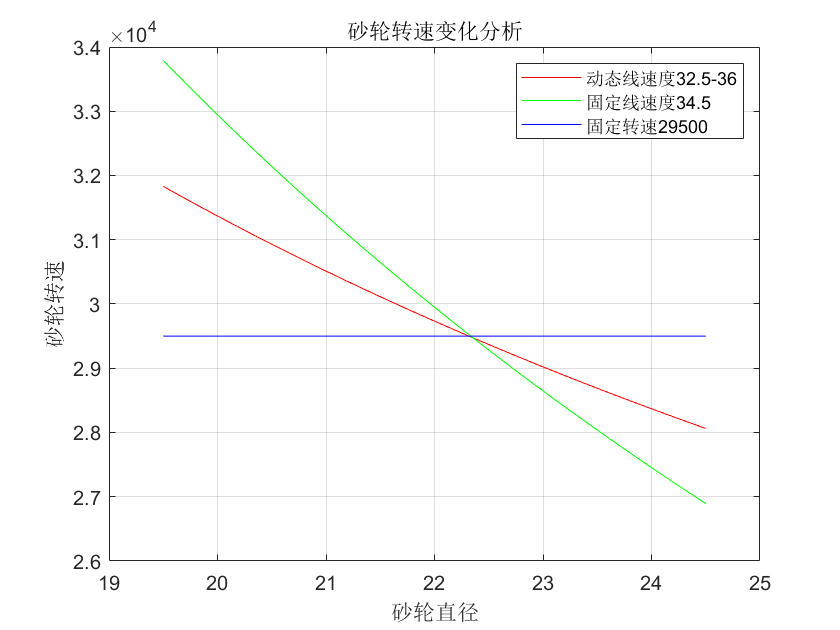

wheelDiaMax = 24.5;
wheelDiaMin = 19.5;
lineSpeedMax = 36;
lineSpeedMin = 32.5;

wheelDiaCurrent = 24.5:-0.1:19.5;
count = length(wheelDiaCurrent(:));

wheelDiaPercent = zeros(1, count);
lineSpeedCurrent = zeros(1, count);
rpmCurrent = zeros(1, count);

for k = 1:count
    wheelDiaPercent(k) = (wheelDiaCurrent(k) - wheelDiaMin) / (wheelDiaMax - wheelDiaMin);
    lineSpeedCurrent(k) = (lineSpeedMax - lineSpeedMin) * wheelDiaPercent(k) + lineSpeedMin;
    rpmCurrent(k) = lineSpeedCurrent(k) * 1000 * 60 / pi / wheelDiaCurrent(k);
end

linSpeedPersist = 34.5;
rpmPersistlinespeed = zeros(1, count);
for k = 1:count
    rpmPersistlinespeed(k) = linSpeedPersist * 1000 * 60 / pi / wheelDiaCurrent(k);
end

rpmPersist = zeros(1, count);
for k = 1:count
    rpmPersist(k) = 29500;
end

plot(wheelDiaCurrent, rpmCurrent, 'r-')
hold on;
plot(wheelDiaCurrent, rpmPersistlinespeed, 'g-')
hold on;
plot(wheelDiaCurrent, rpmPersist, 'b-')

title('砂轮转速变化分析');
xlabel('砂轮直径');
ylabel('砂轮转速');
legend('动态线速度32.5-36', '固定线速度34.5', '固定转速29500');
grid on;